clc; clear all;
robot_name = 'kukaIiwa7';
robot = loadrobot(robot_name, 'DataFormat', 'column');

Loading **KukaIiwa7** Robot

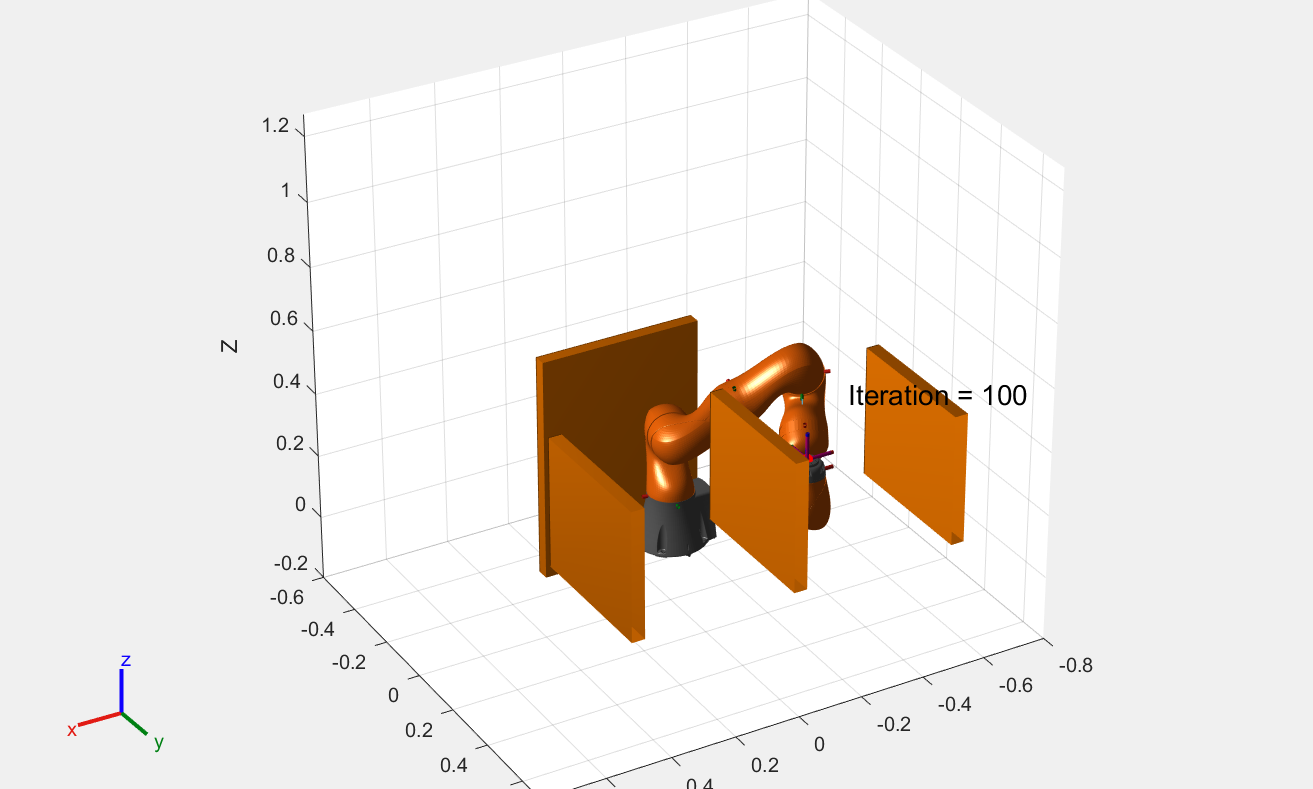

numJoints = numel(homeConfiguration(robot));
endEffector = 'iiwa_link_ee_kuka';
helperCreateObstaclesKINOVA;

%{
%taskInit = trvec2tform([[0.4 0 0.2]])*axang2tform([0 1 0 pi]);
%taskInit = trvec2tform([[0.3 0.0 0.5]])*axang2tform([0 1 0 pi]);%scn2old

R_horizontal = [1  0  0;    % x-axis: to the right
                0  0  1;    % y-axis: upward (for constraint)
                0 -1  0];   % z-axis: forward horizontally

taskInit = trvec2tform([0.3 0.0 0.5]) * rotm2tform(R_horizontal);
ik = inverseKinematics('RigidBodyTree', robot);
ik.SolverParameters.AllowRandomRestart = false;
weights = [1 1 1 1 1 1];

currentRobotJConfig = findCollisionFreeIK(robot, world, endEffector, taskInit);

  
%taskFinal = trvec2tform([0.25 0.0 0.05])*axang2tform([0 1 0 pi]);% Scene 2
taskFinal = trvec2tform([0.25 0.0 0.05]) * rotm2tform(R_horizontal);% Scene 2 old
anglesFinal = rotm2eul(taskFinal(1:3,1:3),'XYZ');
poseFinal = [taskFinal(1:3,4);anglesFinal'];

finalRobotJConfig   = findCollisionFreeIK(robot, world, endEffector, taskFinal);

assert(~checkCollision(robot,currentRobotJConfig,world,"IgnoreSelfCollision","on"))
assert(~checkCollision(robot,finalRobotJConfig,
world,"IgnoreSelfCollision","on"))
%}
%NEW SCENARIOS
%%%%%%%%%%%%%%%% Scene 1 %%%%%%%%%%%%%%%%
% taskInit = trvec2tform([[0.3 0.0 0.4]])*axang2tform([0 1 1 pi]);
% taskFinal = trvec2tform([0.35 0.55 0.35])*axang2tform([0 1 0 pi]);  
% anglesFinal = rotm2eul(taskFinal(1:3,1:3),'XYZ');
% poseFinal = [taskFinal(1:3,4);anglesFinal'];
% ik = inverseKinematics('RigidBodyTree', robot);
% ik.SolverParameters.AllowRandomRestart = false;
% weights = [1 1 1 1 1 1];
%%%%%%%%%%%%%%%% Scene 1 %%%%%%%%%%%%%%%%
%%%%%%%%%%%%%%%% Scene 2 %%%%%%%%%%%%%%%%
taskInit = trvec2tform([[0.2 0.4 0.4]])*axang2tform([0 0 1 pi]);
taskFinal = trvec2tform([-0.2 0.4 0.4])*axang2tform([0 0 1 pi]);  
anglesFinal = rotm2eul(taskFinal(1:3,1:3),'XYZ');
poseFinal = [taskFinal(1:3,4);anglesFinal'];
ik = inverseKinematics('RigidBodyTree', robot);
ik.SolverParameters.AllowRandomRestart = false;
weights = [1 1 1 1 1 1];
%%%%%%%%%%%%%%%% Scene 2 %%%%%%%%%%%%%%%%
%%%%%%%%%%%%%%%% Scene 3 %%%%%%%%%%%%%%%%
% taskInit = trvec2tform([[0.1 0.4 0.1]])*axang2tform([1 0 -1 pi]);
% taskFinal = trvec2tform([-0.1 0.4 0.6])*axang2tform([1 0 1 pi]);  
% anglesFinal = rotm2eul(taskFinal(1:3,1:3),'XYZ');
% poseFinal = [taskFinal(1:3,4);anglesFinal'];
% ik = inverseKinematics('RigidBodyTree', robot);
% ik.SolverParameters.AllowRandomRestart = false;
% weights = [1 1 1 1 1 1]; 
%%%%%%%%%%%%%%%% Scene 3 %%%%%%%%%%%%%%%%
currentRobotJConfig = findCollisionFreeIK(robot, world, endEffector, taskInit);
finalRobotJConfig   = findCollisionFreeIK(robot, world, endEffector, taskFinal);

assert(~checkCollision(robot,currentRobotJConfig,world,"IgnoreSelfCollision","on"))
assert(~checkCollision(robot,finalRobotJConfig,   world,"IgnoreSelfCollision","on"))


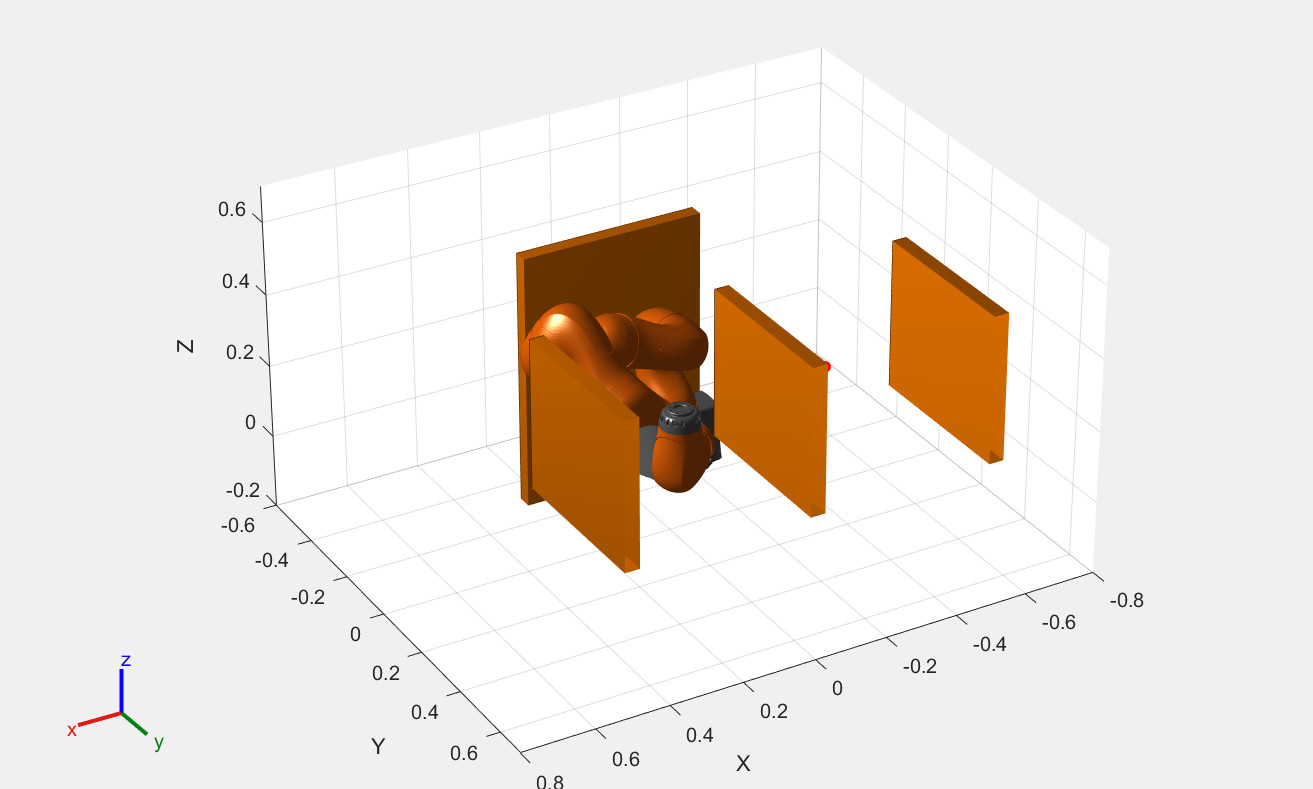

x0 = [currentRobotJConfig', zeros(1,numJoints)];
helperInitialVisualizerKINOVA;

safetyDistance = 0.01; 

Elapsed time is 1.197314 seconds.


Qtheta = 61.7276

RAR = 5.9294

Previous Qθ = 62.079969 | New Qθ = 61.727609 | ΔQ = 0.352359
Elapsed time is 1.043396 seconds.


Qtheta = 61.5597

RAR = 5.9294

Previous Qθ = 61.727609 | New Qθ = 61.559691 | ΔQ = 0.167918
Elapsed time is 1.004224 seconds.


Qtheta = 61.2705

RAR = 5.9294

Previous Qθ = 61.559691 | New Qθ = 61.270512 | ΔQ = 0.289179
Elapsed time is 1.054861 seconds.


Qtheta = 58.7964

RAR = 5.9294

Previous Qθ = 61.270512 | New Qθ = 58.796384 | ΔQ = 2.474128
Elapsed time is 1.019468 seconds.


Qtheta = 59.1994

RAR = 5.9295

Previous Qθ = 58.796384 | New Qθ = 59.199420 | ΔQ = 0.403036
Elapsed time is 1.002793 seconds.


Qtheta = 59.0804

RAR = 5.9295

Previous Qθ = 59.199420 | New Qθ = 59.080365 | ΔQ = 0.119055
Elapsed time is 1.033094 seconds.


Qtheta = 59.6831

RAR = 5.9296

Previous Qθ = 59.080365 | New Qθ = 59.683120 | ΔQ = 0.602755
Elapsed time is 1.070277 seconds.


Qtheta = 59.5002

RAR = 5.9297

Previous Qθ = 59.683120 | New Qθ = 59.500186 | ΔQ = 0.182934
Elapsed time is 1.051880 seconds.


Qtheta = 58.9972

RAR = 5.9297

Previous Qθ = 59.500186 | New Qθ = 58.997226 | ΔQ = 0.502960
Elapsed time is 0.996447 seconds.


Qtheta = 59.2317

RAR = 5.9296

Previous Qθ = 58.997226 | New Qθ = 59.231684 | ΔQ = 0.234459
Elapsed time is 0.995694 seconds.


Qtheta = 55.3591

RAR = 5.9297

Previous Qθ = 59.231684 | New Qθ = 55.359127 | ΔQ = 3.872557
Elapsed time is 0.985361 seconds.


Qtheta = 56.0319

RAR = 5.9297

Previous Qθ = 55.359127 | New Qθ = 56.031871 | ΔQ = 0.672743
Elapsed time is 0.987766 seconds.


Qtheta = 56.7786

RAR = 5.9296

Previous Qθ = 56.031871 | New Qθ = 56.778607 | ΔQ = 0.746737
Elapsed time is 0.986448 seconds.


Qtheta = 56.4681

RAR = 5.9296

Previous Qθ = 56.778607 | New Qθ = 56.468083 | ΔQ = 0.310525
Elapsed time is 0.981982 seconds.


Qtheta = 56.0633

RAR = 5.9297

Previous Qθ = 56.468083 | New Qθ = 56.063310 | ΔQ = 0.404773
Elapsed time is 1.023198 seconds.


Qtheta = 56.3755

RAR = 5.9297

Previous Qθ = 56.063310 | New Qθ = 56.375479 | ΔQ = 0.312169
Elapsed time is 0.987797 seconds.


Qtheta = 50.9587

RAR = 5.9297

Previous Qθ = 56.375479 | New Qθ = 50.958700 | ΔQ = 5.416779
Elapsed time is 0.986311 seconds.


Qtheta = 48.0867

RAR = 5.9297

Previous Qθ = 50.958700 | New Qθ = 48.086715 | ΔQ = 2.871985
Elapsed time is 0.994504 seconds.


Qtheta = 47.5312

RAR = 5.9297

Previous Qθ = 48.086715 | New Qθ = 47.531183 | ΔQ = 0.555532
Elapsed time is 0.985781 seconds.


Qtheta = 48.3489

RAR = 5.9299

Previous Qθ = 47.531183 | New Qθ = 48.348882 | ΔQ = 0.817699
Elapsed time is 0.992872 seconds.


Qtheta = 47.3101

RAR = 5.9299

Previous Qθ = 48.348882 | New Qθ = 47.310090 | ΔQ = 1.038792
Elapsed time is 1.004752 seconds.


Qtheta = 47.0227

RAR = 5.9299

Previous Qθ = 47.310090 | New Qθ = 47.022652 | ΔQ = 0.287439
Elapsed time is 0.991059 seconds.


Qtheta = 47.9291

RAR = 5.9299

Previous Qθ = 47.022652 | New Qθ = 47.929098 | ΔQ = 0.906447
Elapsed time is 0.993628 seconds.


Qtheta = 48.9937

RAR = 5.9299

Previous Qθ = 47.929098 | New Qθ = 48.993722 | ΔQ = 1.064624
Elapsed time is 1.000593 seconds.


Qtheta = 45.8063

RAR = 5.9299

Previous Qθ = 48.993722 | New Qθ = 45.806328 | ΔQ = 3.187393
Elapsed time is 0.988264 seconds.


Qtheta = 45.3220

RAR = 5.9300

Previous Qθ = 45.806328 | New Qθ = 45.322015 | ΔQ = 0.484313
Elapsed time is 0.984576 seconds.


Qtheta = 44.0909

RAR = 5.9301

Previous Qθ = 45.322015 | New Qθ = 44.090876 | ΔQ = 1.231139
Elapsed time is 0.992714 seconds.


Qtheta = 43.6144

RAR = 5.9302

Previous Qθ = 44.090876 | New Qθ = 43.614386 | ΔQ = 0.476490
Elapsed time is 0.999177 seconds.


Qtheta = 39.6014

RAR = 5.9302

Previous Qθ = 43.614386 | New Qθ = 39.601377 | ΔQ = 4.013009
Elapsed time is 1.008939 seconds.


Qtheta = 39.1794

RAR = 5.9302

Previous Qθ = 39.601377 | New Qθ = 39.179370 | ΔQ = 0.422007
Elapsed time is 1.007119 seconds.


Qtheta = 39.0587

RAR = 5.9303

Previous Qθ = 39.179370 | New Qθ = 39.058725 | ΔQ = 0.120644
Elapsed time is 1.010756 seconds.


Qtheta = 37.9718

RAR = 5.9302

Previous Qθ = 39.058725 | New Qθ = 37.971790 | ΔQ = 1.086935
Elapsed time is 0.987031 seconds.


Qtheta = 38.1948

RAR = 5.9302

Previous Qθ = 37.971790 | New Qθ = 38.194845 | ΔQ = 0.223055
Elapsed time is 0.989610 seconds.


Qtheta = 37.9989

RAR = 5.9302

Previous Qθ = 38.194845 | New Qθ = 37.998900 | ΔQ = 0.195945
Elapsed time is 0.989123 seconds.


Qtheta = 36.8049

RAR = 5.9302

Previous Qθ = 37.998900 | New Qθ = 36.804887 | ΔQ = 1.194013
Elapsed time is 0.999001 seconds.


Qtheta = 34.0892

RAR = 5.9303

Previous Qθ = 36.804887 | New Qθ = 34.089156 | ΔQ = 2.715731
Elapsed time is 0.989564 seconds.


Qtheta = 32.4202

RAR = 5.9303

Previous Qθ = 34.089156 | New Qθ = 32.420223 | ΔQ = 1.668934
Elapsed time is 0.999020 seconds.


Qtheta = 30.1664

RAR = 5.9303

Previous Qθ = 32.420223 | New Qθ = 30.166447 | ΔQ = 2.253776
Elapsed time is 0.995138 seconds.


Qtheta = 28.9458

RAR = 5.9304

Previous Qθ = 30.166447 | New Qθ = 28.945766 | ΔQ = 1.220680
Elapsed time is 0.993502 seconds.


Qtheta = 29.4967

RAR = 5.9304

Previous Qθ = 28.945766 | New Qθ = 29.496657 | ΔQ = 0.550891
Elapsed time is 1.000581 seconds.


Qtheta = 29.5014

RAR = 5.9304

Previous Qθ = 29.496657 | New Qθ = 29.501432 | ΔQ = 0.004775
STOMP Finished.


isTrajectoryInCollision = logical
   1


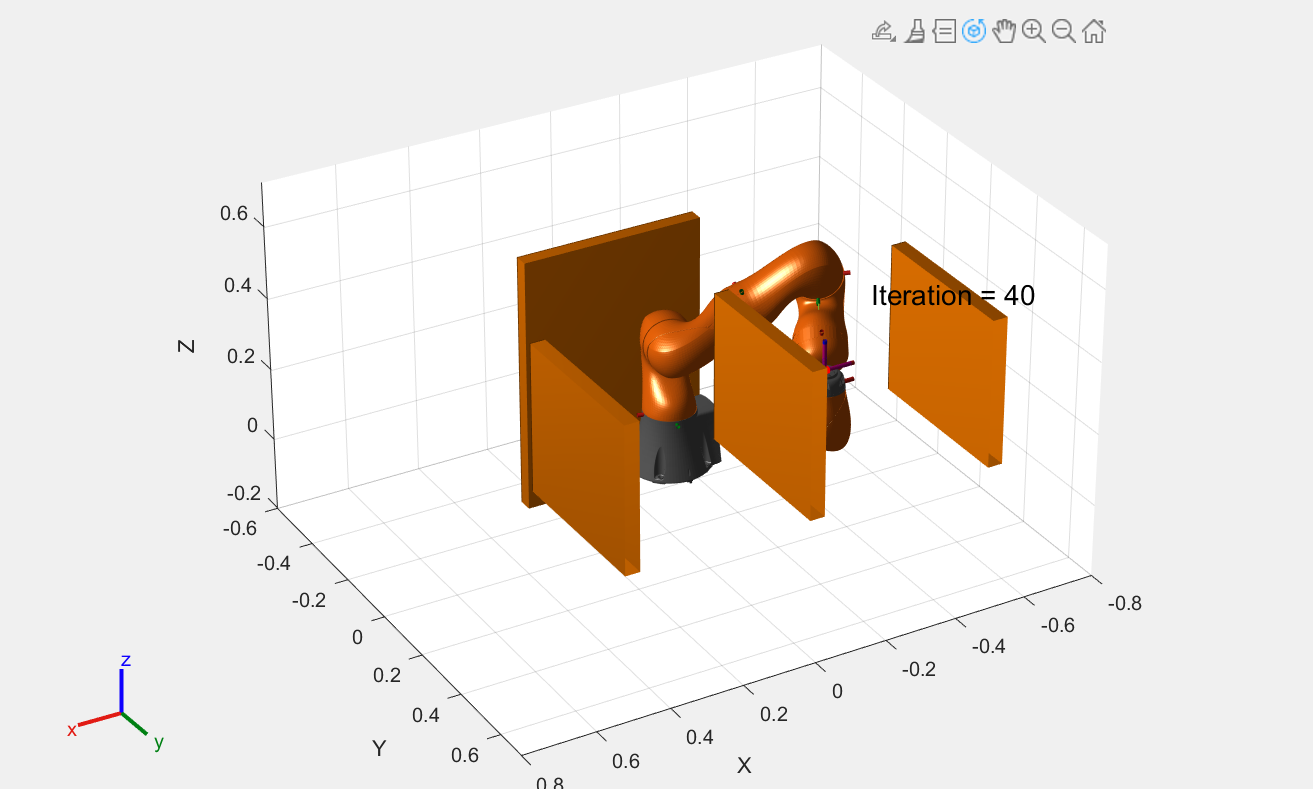

enableVideoTraining = 1;
enableVideo = 1; 
displayAnimation = 1;
helperSTOMP;